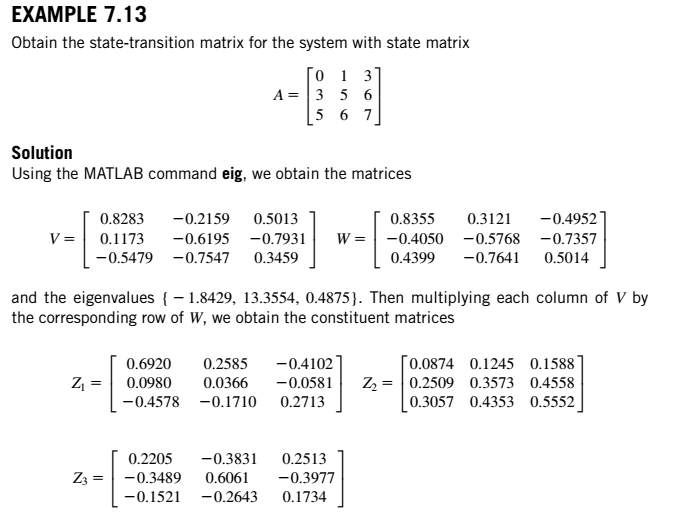

A = [0 1 3; ...
    3 5 6; ...
    5 6 7]

A =      0     1     3
     3     5     6
     5     6     7


[V,W,eigVal] = eig(A)

V =    -0.2159   -0.8283    0.5013
   -0.6195   -0.1173   -0.7931
   -0.7547    0.5479    0.3459


W =    13.3554         0         0
         0   -1.8429         0
         0         0    0.4875


eigVal =    -0.3975   -0.8190    0.4337
   -0.5661   -0.3060   -0.7534
   -0.7221    0.4854    0.4943



latex(sym(A))

ans = '\left(\begin{array}{ccc} 0 & 1 & 3\\ 3 & 5 & 6\\ 5 & 6 & 7 \end{array}\right)'

## Ogata Modern Control System Examples

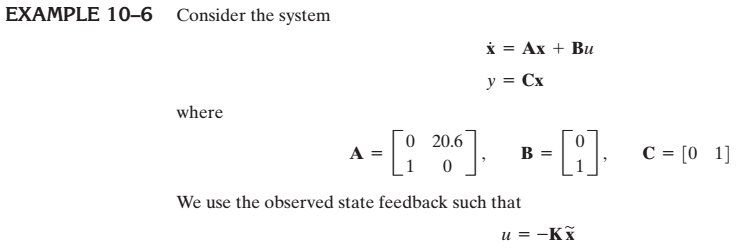

% 10.6
A = [0 20.6; 1 0]

A =          0   20.6000
    1.0000         0


B = [0; 1]

B =      0
     1


C = [0 1]

C =      0     1


O = det([C; C*A])

O = -1

O1 =[C; C*A]

O1 =      0     1
     1     0


Atitl = [1 0; 0 1]

Atitl =      1     0
     0     1


WN = inv(O1)*(inv(Atitl))

WN =      0     1
     1     0


alpha = [100; 20]

alpha =    100
    20


a = [-20.6; 0]

a =   -20.6000
         0


ke = alpha -a

ke =   120.6000
   20.0000


% Ackermann's forumla
Ke = [A^2+20*A+100*eye(2)]*[0 1; 1 0]*B

Ke =   120.6000
   20.0000


Another example 10.7

% hmm
syms s
simplify((s+1.8-j*2.4)*(s+1.8+j*2.4))

$$ans = s^{2}+\frac{18\,s}{5}+9$$

## ELEC 460 April 2015 Final

% Find the z-transform of:
syms k z
fk = heaviside(k)-heaviside(k-10)+ ...
    (k-11)*exp(-2*(k-11))

$$fk = \mathrm{heaviside}\left(k\right)-\mathrm{heaviside}\left(k-10\right)+{\mathrm{e}}^{22-2\,k}\,\left(k-11\right)$$

Fk = ztrans(fk,z)

$$Fk = \frac{1}{z-1}-\frac{\frac{1}{z-1}+\frac{1}{2}}{z^{10}}-\frac{11\,z\,{\mathrm{e}}^{22}}{z-{\mathrm{e}}^{-2}}+\frac{z\,{\mathrm{e}}^{24}}{{\left(z\,{\mathrm{e}}^{2}-1\right)}^{2}}+\frac{1}{2}$$

% See https://www.wolframalpha.com/input/?i=ztransform+(heaviside(t)-+heaviside(t-10)%2B(t-10)exp(-2(t-10))*heaviside(t-11))

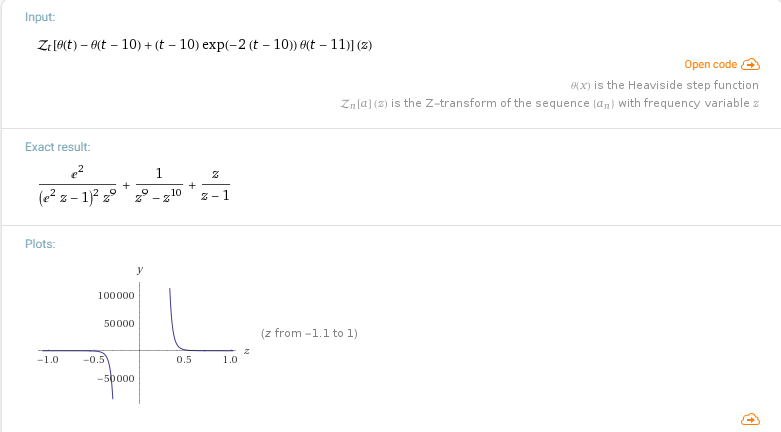

% Find the inverse z-transform of
F2b = (z+2)/(z^2-1)

$$F2b = \frac{z+2}{z^{2}-1}$$

iztrans(F2b,k)

$$ans = \frac{{\left(-1\right)}^{k}}{2}-2\,\delta_{k,0}+\frac{3}{2}$$

% https://www.wolframalpha.com/input/?i=inverse+z-transform+((z%2B2)%2F(z%5E2-1))

Find w(k) for a system described by:

0.1w(k)+0.3w(k+1)-w(k+2)=0, w(0)=2, w(1)=0

Wz = (2*z-0.6)/((z-0.5)*(z+0.2))

$$Wz = \frac{2\,z-\frac{3}{5}}{\left(z-\frac{1}{2}\right)\,\left(z+\frac{1}{5}\right)}$$

partfrac(Wz)

$$ans = \frac{8}{7\,\left(2\,z-1\right)}+\frac{50}{7\,\left(5\,z+1\right)}$$

iztrans(Wz,k)

$$ans = \frac{8\,{\left(\frac{1}{2}\right)}^{k}}{7}-\frac{50\,{\left(-\frac{1}{5}\right)}^{k}}{7}+6\,\delta_{k,0}$$

Root locus of Question 3

Gs = tf([0.4 2.8],[1 2 0 ])


Gs =
 
  0.4 s + 2.8
  -----------
   s^2 + 2 s
 
Continuous-time transfer function.



Gz = c2d(Gs,0.1,'ZOH')


Gz =
 
   0.04937 z - 0.02399
  ----------------------
  z^2 - 1.819 z + 0.8187
 
Sample time: 0.1 seconds
Discrete-time transfer function.



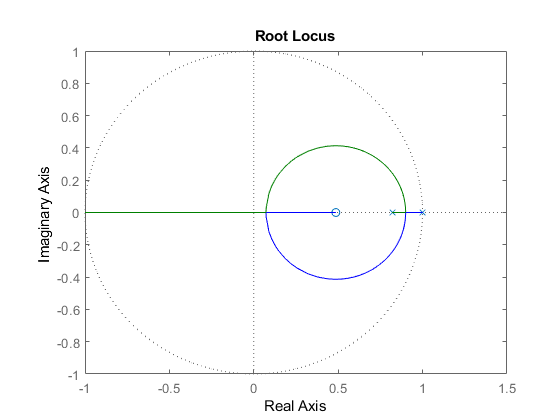

rlocus(Gz)

symsFun = (z^2-1.8187*z+0.8187)/(0.04935*(z-0.4857))

$$symsFun = \frac{z^{2}-\frac{18187\,z}{10000}+\frac{8187}{10000}}{\frac{987\,z}{20000}-\frac{4793859}{200000000}}$$

testing = vpa(diff(symsFun,z),5)

$$testing = \frac{2.0\,z-1.8187}{0.04935\,z-0.023969}-\frac{0.04935\,\left(z^{2}-1.8187\,z+0.8187\right)}{{\left(0.04935\,z-0.023969\right)}^{2}}$$

simpleFrac = vpa(simplifyFraction(testing),5)

$$simpleFrac = \frac{10.0\,\left(4.935\,10^{65}\,z^{2}-4.7939\,10^{65}\,z+3.1901\,10^{64}\right)}{{\left(4.935\,10^{32}\,z-2.3969\,10^{32}\right)}^{2}}$$

eqn1 = testing == 0

$$eqn1 = \frac{2.0\,z-1.8187000000000352883944287896156}{0.049349999999996896349330199882388\,z-0.023969295000000556683517061173916}-\frac{0.049349999999996896349330199882388\,\left(z^{2}-1.8187000000000352883944287896156\,z+0.81870000000003528839442878961563\right)}{{\left(0.049349999999996896349330199882388\,z-0.023969295000000556683517061173916\right)}^{2}}=0$$

% Finding breakaway, break in points    
solve(eqn1,z)

$$ans = \left(\begin{array}{c} 0.071861988212841798146634818391385\\ 0.89953801178724185440239793625316 \end{array}\right)$$

pz = [1 -0.7 0.1 -0.35]

pz =     1.0000   -0.7000    0.1000   -0.3500


[P, L] = jury(pz,15)

$$P = \left(\begin{array}{cccc} -0.35 & 0.1 & -0.7 & 1.0\\ 1.0 & -0.7 & 0.1 & -0.35\\ -0.145 & -0.665 & 0.8775 & 0\\ 0.8775 & -0.665 & -0.145 & 0\\ -0.77488603988603988603988603988604 & 0.85353988603988603988603988603989 & 0 & 0\\ 0.85353988603988603988603988603989 & -0.77488603988603988603988603988604 & 0 & 0\\ 0.1500597269624573378839590443686 & 0 & 0 & 0\\ 0.1500597269624573378839590443686 & 0 & 0 & 0 \end{array}\right)$$

$$L = \left(\begin{array}{c} 0.8775\\ 0.85353988603988603988603988603989\\ 0.1500597269624573378839590443686 \end{array}\right)$$

% last question lol
syms s t
A = [-1 1; ...
     0 2]

A =     -1     1
     0     2


Atest = s*eye(2)-A

$$Atest = \left(\begin{array}{cc} s+1 & -1\\ 0 & s-2 \end{array}\right)$$

b = [0; 2]

b =      0
     2


T = 1/2

T = 0.5000

G = ilaplace([inv(Atest)])

$$G = \left(\begin{array}{cc} {\mathrm{e}}^{-t} & \frac{{\mathrm{e}}^{2\,t}}{3}-\frac{{\mathrm{e}}^{-t}}{3}\\ 0 & {\mathrm{e}}^{2\,t} \end{array}\right)$$

H = int(G*b,0,T)

$$H = \left(\begin{array}{c} \frac{\mathrm{e}}{3}+\frac{2\,{\mathrm{e}}^{-\frac{1}{2}}}{3}-1\\ \mathrm{e}-1 \end{array}\right)$$

% lazy answer
K = [-2.0118 -0.1965]* [1 2.118; 0 1]*[0 1.40783; 2 2*exp(1)]

K =    -8.9150  -27.0657


% tracking signal part
c = [1 0]

c =      1     0


h = 1/(c*inv(((eye(2)-vpa(G,5)+vpa(H,5)*K)))*vpa(H,5))

$$h = \begin{array}{l} \frac{1}{\frac{1.8471529655935455593862570822239\,\left(7751937984495683384349916216939.0\,{\mathrm{e}}^{3.0\,t}+195406720018381641754410350184466.0\,{\mathrm{e}}^{t}-7751937984495683384349916216939.0\right)}{\sigma_{1}}-\frac{1.5522385798067261930555105209351\,{\mathrm{e}}^{t}\,\left(5000000000000000000000000000000.0\,{\mathrm{e}}^{2.0\,t}+227532619066718313067034038070300.0\right)}{\sigma_{1}}}\\ \mathrm{where}\\ \sigma_{1}=25000000000000000000000000000000.0\,{\mathrm{e}}^{2.0\,t}-83462886465483263607970142363503.0\,{\mathrm{e}}^{3.0\,t}-1.2068540120583443273028383868395\,10^{33}\,{\mathrm{e}}^{t}+1.265316898523827590910808529203\,10^{33} \end{array}$$

h = subs(t,0.5)

$$h = \frac{1}{2}$$

## APRIL 2011 ELEC 460 Final Exam

GR = 0.68*z/((z-1)^2*(z-0.8)*(z-+0.7))

$$GR = \frac{17\,z}{25\,{\left(z-1\right)}^{2}\,\left(z-\frac{4}{5}\right)\,\left(z-\frac{7}{10}\right)}$$

y = iztrans(GR,k)

$$y = \frac{34\,k}{3}+170\,{\left(\frac{4}{5}\right)}^{k}-\frac{680\,{\left(\frac{7}{10}\right)}^{k}}{9}-\frac{850}{9}$$

A = [-1 1; 1 -2]

A =     -1     1
     1    -2


B = [1; 0]

B =      1
     0


C = [0 1]

C =      0     1


Ts = 0.1

Ts = 0.1000

sys = ss(A,B,C,0)


sys =
 
  A = 
       x1  x2
   x1  -1   1
   x2   1  -2
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sysCTS = ss(A,B,C,0)


sysCTS =
 
  A = 
       x1  x2
   x1  -1   1
   x2   1  -2
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sysDis = c2d(sysCTS,Ts)


sysDis =
 
  A = 
            x1       x2
   x1   0.9092  0.08625
   x2  0.08625    0.823
 
  B = 
             u1
   x1   0.09531
   x2  0.004532
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



[num,den] = ss2tf(A,B,C,0)

num =      0     0     1


den =      1     3     1


g5CTS = tf(num,den)


g5CTS =
 
        1
  -------------
  s^2 + 3 s + 1
 
Continuous-time transfer function.



g5Discrete = c2d(g5CTS,Ts)


g5Discrete =
 
  0.004532 z + 0.004101
  ----------------------
  z^2 - 1.732 z + 0.7408
 
Sample time: 0.1 seconds
Discrete-time transfer function.




check = partfrac(-1/(s*(s^2+3*s+1)))

$$check = \frac{s+3}{s^{2}+3\,s+1}-\frac{1}{s}$$

transCheck = ilaplace(check)

$$transCheck = {\mathrm{e}}^{-\frac{3\,t}{2}}\,\left(\cosh\left(\frac{\sqrt{5}\,t}{2}\right)+\frac{3\,\sqrt{5}\,\sinh\left(\frac{\sqrt{5}\,t}{2}\right)}{5}\right)-1$$

animeCheck = ztrans(transCheck)

$$animeCheck = \begin{array}{l} \frac{3\,\sqrt{5}\,z\,\sinh\left(\frac{\sqrt{5}}{2}\right)\,{\mathrm{e}}^{3/2}}{5\,\sigma_{1}}-\frac{z\,{\mathrm{e}}^{3/2}\,\left(\cosh\left(\frac{\sqrt{5}}{2}\right)-z\,{\mathrm{e}}^{3/2}\right)}{\sigma_{1}}-\frac{z}{z-1}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{3}\,z^{2}-2\,\cosh\left(\frac{\sqrt{5}}{2}\right)\,{\mathrm{e}}^{3/2}\,z+1 \end{array}$$

A = [s+1 1; 1 s+2]

$$A = \left(\begin{array}{cc} s+1 & 1\\ 1 & s+2 \end{array}\right)$$

G6 = ilaplace(inv(A))

$$G6 = \begin{array}{l} \left(\begin{array}{cc} {\mathrm{e}}^{-\frac{3\,t}{2}}\,\left(\cosh\left(\frac{\sqrt{5}\,t}{2}\right)+\frac{\sqrt{5}\,\sinh\left(\frac{\sqrt{5}\,t}{2}\right)}{5}\right) & \sigma_{1}\\ \sigma_{1} & {\mathrm{e}}^{-\frac{3\,t}{2}}\,\left(\cosh\left(\frac{\sqrt{5}\,t}{2}\right)-\frac{\sqrt{5}\,\sinh\left(\frac{\sqrt{5}\,t}{2}\right)}{5}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{2\,\sqrt{5}\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\sinh\left(\frac{\sqrt{5}\,t}{2}\right)}{5} \end{array}$$

G6fin = subs(G6,t,0.1)

$$G6fin = \begin{array}{l} \left(\begin{array}{cc} {\mathrm{e}}^{-\frac{3}{20}}\,\left(\cosh\left(\frac{\sqrt{5}}{20}\right)+\frac{\sqrt{5}\,\sinh\left(\frac{\sqrt{5}}{20}\right)}{5}\right) & \sigma_{1}\\ \sigma_{1} & {\mathrm{e}}^{-\frac{3}{20}}\,\left(\cosh\left(\frac{\sqrt{5}}{20}\right)-\frac{\sqrt{5}\,\sinh\left(\frac{\sqrt{5}}{20}\right)}{5}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{2\,\sqrt{5}\,\sinh\left(\frac{\sqrt{5}}{20}\right)\,{\mathrm{e}}^{-\frac{3}{20}}}{5} \end{array}$$

G6fin = vpa(G6fin,8)

$$G6fin = \left(\begin{array}{cc} 0.90921812 & -0.086250224\\ -0.086250224 & 0.8229679 \end{array}\right)$$

testmore = -1/(s^2+3*s+1)

$$testmore = -\frac{1}{s^{2}+3\,s+1}$$

betterWork = subs(testmore,s,2/Ts*(z-1)/(z+1))

$$betterWork = -\frac{1}{\frac{{\left(20\,z-20\right)}^{2}}{{\left(z+1\right)}^{2}}+\frac{3\,\left(20\,z-20\right)}{z+1}+1}$$

simplify(betterWork)

$$ans = -\frac{{\left(z+1\right)}^{2}}{461\,z^{2}-798\,z+341}$$

gfinalRL = g5Discrete*zpk([0],[1],1,0.1)


gfinalRL =
 
    0.0045317 z (z+0.9049)
  ---------------------------
  (z-0.9625) (z-1) (z-0.7697)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.



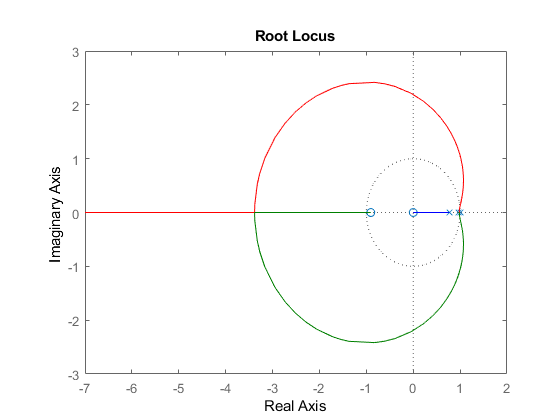

rlocus(gfinalRL)

syms z
Yz = z*(z-1)/(z^2-z+0.7)

$$Yz = \frac{z\,\left(z-1\right)}{z^{2}-z+\frac{7}{10}}$$

y =iztrans(Yz)

$$y = -\frac{7\,{\left(-1\right)}^{n}\,\sqrt{5}\,10^{1-n}\,{\left(-5-3\,\sqrt{5}\,\mathrm{i}\right)}^{n-1}\,\mathrm{i}}{30}+\frac{7\,{\left(-1\right)}^{n}\,\sqrt{5}\,10^{1-n}\,{\left(-5+3\,\sqrt{5}\,\mathrm{i}\right)}^{n-1}\,\mathrm{i}}{30}$$


RL7= zpk([0,-0.8],[0.8,0.3,1],1,1)


RL7 =
 
        z (z+0.8)
  ---------------------
  (z-0.8) (z-1) (z-0.3)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



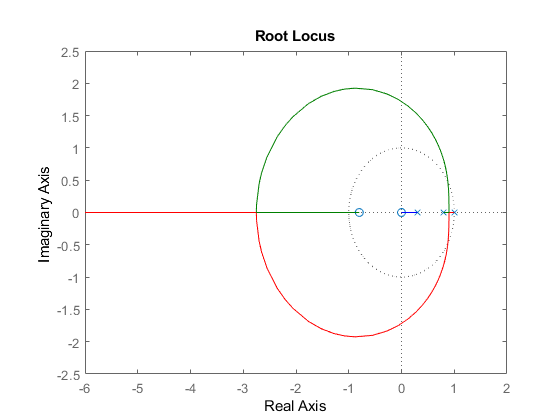

rlocus(RL7)